# **RS-HL-14: Multi User Congestion Game**

**Hongseok Kim**

**UT Austin Oden Institute**

**08/02/24**

### **Configuration of Congestion Game**


$$\textrm{Algorithm}\;\textrm{for}\;C$$


### **I. Load the Dataset**

clear;clc;
% Load the Satellite Contat Dataset
addpath('~/Desktop/Redstone_Project/RS_HL/RS_HL_10_TV_MDP_Functions')
load('~/RS_Dataset/RS_HL_3_dataset.mat')

### II. Destination Setting and Time Index Vector Setting

time_index_vector = 100:130;
start_time_index = 100:120;

number_of_agents = 100;
number_of_destinations = 5;
state_vector = 1:48;

start_state = state_vector(randi(numel(state_vector), 1, number_of_agents));
destination_values = randsample(state_vector,number_of_destinations);
destination_state = destination_values(randi(numel(destination_values), 1, number_of_agents));
start_time = start_time_index(randi(numel(start_time_index), 1, number_of_agents));

#### II.1 Run the MDP simulation for each destination

fprintf('Total Number of Destinations: %d\n', number_of_destinations);

Total Number of Destinations: 5


for destination_index = 1:number_of_destinations
    fprintf('--------------------------------------\n')
    fprintf('Running MDP %d / %d , Destination %d \n', destination_index,number_of_destinations,destination_values(destination_index));
    MDP.(['MDP', num2str(destination_values(destination_index))]) = runMDP(sat_to_sat_contact_3d_matrix, time_index_vector,destination_values(destination_index));

end

--------------------------------------


Running MDP 1 / 5 , Destination 38 


simulation set up complete! 
Policy: 1 -> Value Iteration: 1008
Policy: 2 -> Value Iteration: 11
Policy: 3 -> Value Iteration: 2
Policy: 4 -> Value Iteration: 2
Policy: 5 -> Value Iteration: 6
Policy: 6 -> Value Iteration: 2
Policy: 7 -> Value Iteration: 1


--------------------------------------


Running MDP 2 / 5 , Destination 7 


simulation set up complete! 
Policy: 1 -> Value Iteration: 1230
Policy: 2 -> Value Iteration: 10
Policy: 3 -> Value Iteration: 2
Policy: 4 -> Value Iteration: 2
Policy: 5 -> Value Iteration: 2
Policy: 6 -> Value Iteration: 2
Policy: 7 -> Value Iteration: 2
Policy: 8 -> Value Iteration: 2
Policy: 9 -> Value Iteration: 2


--------------------------------------


Running MDP 3 / 5 , Destination 2 


simulation set up complete! 
Policy: 1 -> Value Iteration: 756
Policy: 2 -> Value Iteration: 11
Policy: 3 -> Value Iteration: 8
Policy: 4 -> Value Iteration: 2
Policy: 5 -> Value Iteration: 2
Policy: 6 -> Value Iteration: 2
Policy: 7 -> Value Iteration: 2
Policy: 8 -> Value Iteration: 2
Policy: 9 -> Value Iteration: 2
Policy: 10 -> Value Iteration: 2
Policy: 11 -> Value Iteration: 2
Policy: 12 -> Value Iteration: 2
Policy: 13 -> Value Iteration: 2
Policy: 14 -> Value Iteration: 2
Policy: 15 -> Value Iteration: 2


--------------------------------------


Running MDP 4 / 5 , Destination 18 


simulation set up complete! 
Policy: 1 -> Value Iteration: 1344
Policy: 2 -> Value Iteration: 10
Policy: 3 -> Value Iteration: 2
Policy: 4 -> Value Iteration: 2
Policy: 5 -> Value Iteration: 4
Policy: 6 -> Value Iteration: 2
Policy: 7 -> Value Iteration: 2
Policy: 8 -> Value Iteration: 2
Policy: 9 -> Value Iteration: 2
Policy: 10 -> Value Iteration: 2
Policy: 11 -> Value Iteration: 2


--------------------------------------


Running MDP 5 / 5 , Destination 33 


simulation set up complete! 
Policy: 1 -> Value Iteration: 681
Policy: 2 -> Value Iteration: 10
Policy: 3 -> Value Iteration: 9
Policy: 4 -> Value Iteration: 2
Policy: 5 -> Value Iteration: 2
Policy: 6 -> Value Iteration: 2
Policy: 7 -> Value Iteration: 1


    fprintf('--------------------------------------\n')

--------------------------------------


### III. Configure each Agent's Setting

agents_input = [start_time', start_state', destination_state'];

### IV. Configure the simulation structure setting

% Level 1: Initialize simulation structure
sim = struct();

for time_index = time_index_vector
    sim.(['time' num2str(time_index)]) = {};
end

% Level 2/3: Initialize Agent (Level 2) with States and Destination (Level 3)

number_of_agents = length(agents_input(:,1));

for agent_index = 1:number_of_agents
   sim.(['time' num2str(agents_input(agent_index,1))]).(['agent' num2str(agent_index)]).('state') = agents_input(agent_index,2);
   sim.(['time' num2str(agents_input(agent_index,1))]).(['agent' num2str(agent_index)]).('destination') = agents_input(agent_index,3);   
end


### V. Configuration of Action Value Structure and Simulation Structure


% Initialize Action Value Structure
action_value_struct = struct();


for time_index = time_index_vector

    % If there's no active agent, continue to next time step
    if isempty(sim.(['time' num2str(time_index)]))
       continue;
    end


    % Parse the number of active agents
    number_of_active_agents = length(fieldnames(sim.(['time' num2str(time_index)])));

    % Make the status matrix represents current and next
    % [current_state, next_state, destination]
    status_matrix = zeros(3, number_of_active_agents);

    agents_list = fieldnames(sim.(['time' num2str(time_index)]));

    % Definine Original Policy Distribution Matrix
    original_policy_matrix = zeros(number_of_active_agents,length(state_vector));

    % Find the Next state from Current Agent-State 
    for active_agent_index = 1:number_of_active_agents
        % Find the Current State and Destination of given agent
        current_state = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('state');
        destination = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('destination');
        
        % Get the Action values and corresponding next states from given state in given MDP
        action_value_vector = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).('action_value_vector');       
        next_state_vector = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).('next_state_vector');

        % Action Value Matrix Config: [Action index, Action Value Q, Next State S'] 
        vector_length = length(action_value_vector);
        action_value_matrix = [(1:vector_length)',action_value_vector, next_state_vector, action_value_vector];
        action_value_matrix = sortrows(action_value_matrix,2, 'descend');
        action_value_struct.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('action_value_matrix') = action_value_matrix;

        % Find the Active Actoin Number from given Original MDP pi distribution
        pi_dist = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).('policy_distribution');
        action_number = find(pi_dist(current_state,:) ~= 0);

        for action_number_index = 1:length(action_number)
          original_policy_matrix(active_agent_index,action_number(action_number_index)) = action_number(action_number_index);
        end

        % Get Activated Next States Vector (Which is from pi distribution)
        activated_next_states = action_number;
        action_value_struct.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('activated_next_states') = activated_next_states;

        if length(action_number) > 1
        action_number = randsample(action_number,1);
        end

        next_state = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('success').('next_state');
        reward = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('success').('reward');
        state_value =  MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).('state_value');
        action_value  = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('action_value'); 

        % Configure Proposed status matrix for the collision test
        status_matrix(1,active_agent_index) = current_state;
        status_matrix(2,active_agent_index) = next_state;
        status_matrix(3,active_agent_index) = destination;

        % Add State Value
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('state_value') = state_value;

        % Save the Original Reward and action value to prepare the update
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('original_action_number') = action_number;
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('original_action_value') = action_value;
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('original_reward') = reward;
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('original_next_state') = next_state;

        % Add the action number, reward, action value (may be changed)
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('action_number') = action_number;        
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('action_value') = action_value;
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('reward') = reward;
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('next_state') = next_state;
    end

### V.1 Policy Iteration By Updating Q values of potential Collision by given policy distribution

    updated_policy_matrix = zeros(number_of_active_agents,length(state_vector));
    policy_iteration = 0;
    congestion_cost_factor = 12;

    while true
    % while isequal(original_policy_matrix,updated_policy_matrix) == false
    policy_iteration  = policy_iteration + 1;

    if policy_iteration > 1
        original_policy_matrix = updated_policy_matrix;
    end    


    for active_agent_index = 1:number_of_active_agents

       action_value_matrix = action_value_struct.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('action_value_matrix');
       action_value_matrix_original = action_value_matrix;

       number_of_actions = length(action_value_matrix(:,1));

       for test_agent_index = 1:number_of_active_agents
          if active_agent_index == test_agent_index
              continue;
          end

          index_starting_next_timestep = find(agents_input(:,1) == time_index+1);
          agents_input_extracted = agents_input(index_starting_next_timestep,:);

          starting_state_list = agents_input_extracted(:,2)';

          test_activated_next_index = original_policy_matrix(active_agent_index);
          text_activated_next_states = test_activated_next_index(test_activated_next_index ~= 0);
          % test_activated_next_states = action_value_struct.(['time' num2str(time_index)]).(agents_list{test_agent_index}).('activated_next_states');       
          test_activated_states = [text_activated_next_states, starting_state_list];

          for action_index = 1:number_of_actions
              action_value_mat_next_state = action_value_matrix(action_index,3);
              congestion_indicator = length(find(test_activated_states == action_value_mat_next_state));
              current_action_value = action_value_matrix(action_index,2);
              updated_action_value = current_action_value - congestion_cost_factor * congestion_indicator;
              action_value_matrix(action_index,4) = updated_action_value;
          end
       end
       % if isequal(action_value_matrix(:,1), action_value_matrix_updated(:,1)) == false
       %      fprintf('there was correctance \n')
       % end


       action_value_struct.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('action_value_matrix') = action_value_matrix;

        % Policy Iteration Process -> Should Be Done

    end


    % Update The Action Number

    for active_agent_index = 1:number_of_active_agents
        % Find the Current State and Destination of given agent
        current_state = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('state');
        destination = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('destination');

        % if current_state == destination
        %     continue;
        % end

        action_value_matrix = action_value_struct.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('action_value_matrix');
        updated_action_value_vector = max(action_value_matrix(:,4));
        updated_action_index = find(updated_action_value_vector == action_value_matrix(:,4));
        updated_action_policy = action_value_matrix(updated_action_index,1);

        for index = 1:length(updated_action_policy)
            updated_policy_matrix(active_agent_index, updated_action_policy(index)) = updated_action_policy(index);
        end


        % Get Activated Next States Vector (Which is from pi distribution)
        activated_next_states_updated = updated_policy_matrix(active_agent_index,:);
        activated_next_states_updated = activated_next_states_updated(activated_next_states_updated ~= 0)'; 
        action_value_struct.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('activated_next_states') = activated_next_states_updated';


        if length(updated_action_index) > 1
        updated_action_index = randsample(updated_action_index,1);
        end

        action_number = action_value_matrix(updated_action_index,1);
        action_value = action_value_matrix(updated_action_index,2);
        next_state = action_value_matrix(updated_action_index,3);
        reward =  MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('success').('reward');

        % Modify Proposed status matrix for the collision test
        status_matrix(1,active_agent_index) = current_state;
        status_matrix(2,active_agent_index) = next_state;
        status_matrix(3,active_agent_index) = destination;

        % Modify the action number, reward, action value (may be changed)
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('action_number') = action_number;        
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('action_value') = action_value;
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('reward') = reward;
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('next_state') = next_state;
        

        % original_action_number = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('original_action_number');
        % Check the Update of the values
        % if isequal(action_number, original_action_number) == false
        %     fprintf('action_number changed from %d to %d \n',original_action_number,action_number)
        %     time_index
        %     agents_list{active_agent_index}
        %     sim.(['time' num2str(time_index)]).(agents_list{active_agent_index})       
        % end

    end

        if isequal(original_policy_matrix,updated_policy_matrix) == true
        break;
        end
    end

    fprintf('Policy Iteration Completed at time %d by %d iterations \n',time_index, policy_iteration)

#### V.1 Propagation With Randomness

    % Break when time index reaches the end time
    if time_index == max(time_index_vector)
       break;
    end

    % Actual Propagation of The State by Time

    for active_agent_index = 1:number_of_active_agents
 

    % Generate Random Factor
    random_factor = rand(1,1);
     
    % Call the Current State, Destination, and Action Number of given agent
    current_state = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('state');
    destination = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('destination');
    action_number = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('action_number');

    transmission_probability = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('success').('transition_probability');
        if random_factor > -1 
        % if random_factor > 1 - transmission_probability 
            % Update the time+1 for next state

            % Don't update the agent already arrived to destination
            if current_state ==  destination
                continue;
            end

            sim.(['time' num2str(time_index+1)]).(agents_list{active_agent_index}).('state') = status_matrix(2,active_agent_index);
            sim.(['time' num2str(time_index+1)]).(agents_list{active_agent_index}).('destination') = status_matrix(3,active_agent_index);


        else
            sim.(['time' num2str(time_index+1)]).(agents_list{active_agent_index}).('state') = current_state;
            sim.(['time' num2str(time_index+1)]).(agents_list{active_agent_index}).('destination') = status_matrix(3,active_agent_index); 
            % Since it is failure, we should replace reward as failure penalty
            failure_reward = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('fail').('reward');
            sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('reward') = failure_reward;
        end
    end
end

Policy Iteration Completed at time 100 by 1 iterations 
Policy Iteration Completed at time 101 by 1 iterations 
Policy Iteration Completed at time 102 by 2 iterations 
Policy Iteration Completed at time 103 by 2 iterations 
Policy Iteration Completed at time 104 by 1 iterations 
Policy Iteration Completed at time 105 by 3 iterations 
Policy Iteration Completed at time 106 by 3 iterations 
Policy Iteration Completed at time 107 by 3 iterations 
Policy Iteration Completed at time 108 by 3 iterations 
Policy Iteration Completed at time 109 by 3 iterations 
Policy Iteration Completed at time 110 by 3 iterations 
Policy Iteration Completed at time 111 by 3 iterations 
Policy Iteration Completed at time 112 by 3 iterations 
Policy Iteration Completed at time 113 by 2 iterations 
Policy Iteration Completed at time 114 by 3 iterations 
Policy Iteration Completed at time 115 by 3 iterations 
Policy Iteration Completed at time 116 by 3 iterations 
Policy Iteration Completed at time 117 by 3 iter

### VI. result display

result_matrix = zeros(length(time_index_vector),number_of_agents);
reward_matrix =  zeros(length(time_index_vector),number_of_agents);
state_value_matrix = zeros(length(time_index_vector),number_of_agents);
action_value_matrix = zeros(length(time_index_vector),number_of_agents);
cumulative_reward_matrix = zeros(length(time_index_vector),number_of_agents);

for time_index = time_index_vector

    if isempty(sim.(['time' num2str(time_index)]))
     continue;
    end

    agents_list = fieldnames(sim.(['time' num2str(time_index)]));
    number_of_agents = length(agents_list);

    for agent_index = 1:number_of_agents
        agent_name = cell2mat(agents_list(agent_index));
        agent_no = regexp(agent_name, '\d+','match');
        agent_number = str2double(agent_no{1});

        result_matrix(time_index - min(time_index_vector) + 1,agent_number) = sim.(['time' num2str(time_index)]).(agent_name).('state');
        reward_matrix(time_index - min(time_index_vector) + 1,agent_number) =  sim.(['time' num2str(time_index)]).(agent_name).('reward');
        state_value_matrix(time_index - min(time_index_vector) + 1,agent_number) = sim.(['time' num2str(time_index)]).(agent_name).('state_value');
        action_value_matrix(time_index - min(time_index_vector) + 1,agent_number) = sim.(['time' num2str(time_index)]).(agent_name).('action_value');
        cumulative_reward_matrix(time_index - min(time_index_vector) + 1,agent_number) = sum(reward_matrix(1:time_index - min(time_index_vector) + 1,agent_number));

    end

end

result = [time_index_vector' , result_matrix]

result =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   101     0     0     0     0     0     0     0     0     0     0    36     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   102     0     0     0     0     0     0     0     0     0     0    16     0     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   103     0     0     0     0     0     0     0     0     0     0    15     0     4    

reward = [time_index_vector', reward_matrix]

reward =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   101     0     0     0     0     0     0     0     0     0     0   -15     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   102     0     0     0     0     0     0     0     0     0     0    -1     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   103     0     0     0     0     0     0     0     0     0     0    -1     0    -1    

cumulative_reward = [time_index_vector', cumulative_reward_matrix]

cumulative_reward =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   101     0     0     0     0     0     0     0     0     0     0   -15     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   102     0     0     0     0     0     0     0     0     0     0   -16     0    -2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   103     0     0     0     0     0     0     0     0     0     0   -17     

state_value = [time_index_vector', state_value_matrix]

state_value =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   101     0     0     0     0     0     0     0     0     0     0    84     0    96     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   102     0     0     0     0     0     0     0     0     0     0    99     0    97     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   103     0     0     0     0     0     0     0     0     0     0    98     0    9

action_value = [time_index_vector', action_value_matrix]

action_value =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   101     0     0     0     0     0     0     0     0     0     0    84     0    96     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   102     0     0     0     0     0     0     0     0     0     0    97     0    97     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   103     0     0     0     0     0     0     0     0     0     0    96     0    

### VI.1 Chack Congestion Factor in Result Matrix

congestion_factor_vector = zeros(length(result(:,1)),1);
active_data_packet= zeros(length(result(:,1)),1);
active_sats = zeros(length(result(:,1)),1);

for result_index = 1:length(result(:,1))
 states_vector = result(result_index,2:end);
 active_agent_vector = states_vector(states_vector ~= 0);
 unique_active_agent_vector = unique(active_agent_vector);
 active_sats(result_index) = length(unique_active_agent_vector);
 active_data_packet(result_index)  = length(active_agent_vector);
 congestion_factor_vector(result_index) = length(active_agent_vector) - length(unique_active_agent_vector);
end

congestion_factor_vector'

ans =      0     0     0     1     1     1     3     4     4     3     6     9    11    14    17    17    13    15    16     8    10     8     7     3     2     3     3     0     1     3     1


congestion_factor_sum = sum(congestion_factor_vector)

congestion_factor_sum = 184

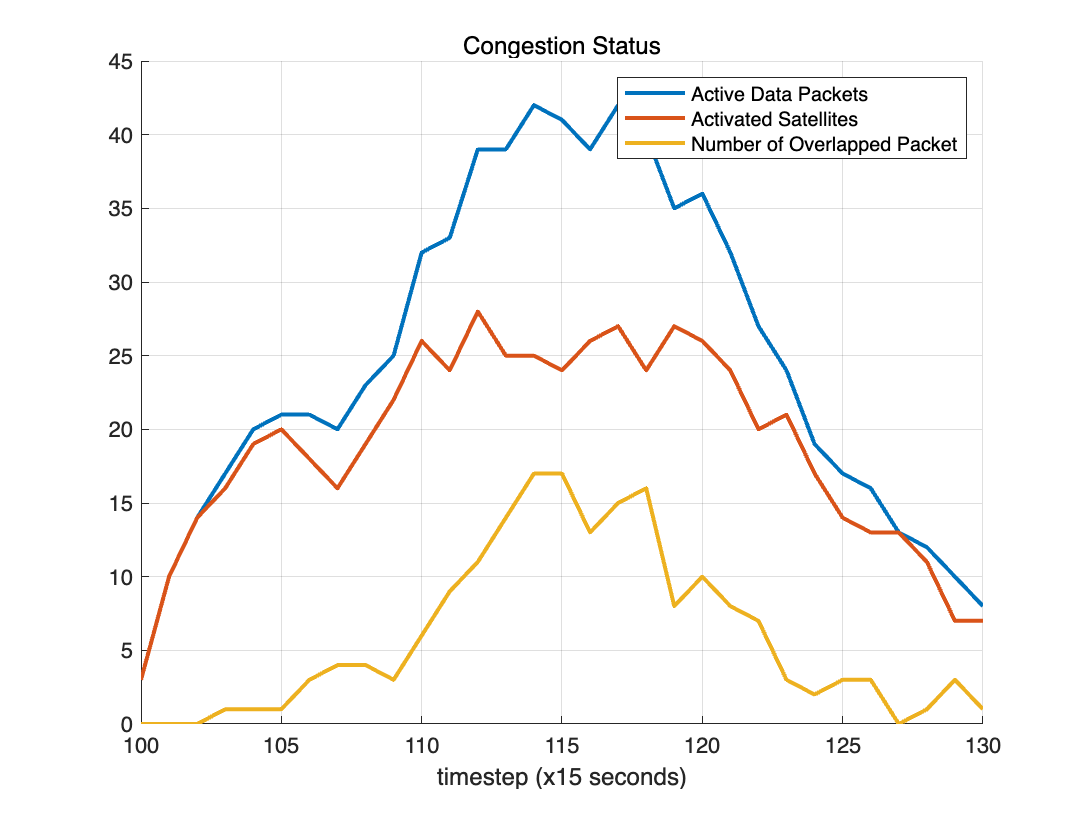

figure;
hold on
plot(time_index_vector',  active_data_packet,'LineWidth',2)
plot(time_index_vector', active_sats,'LineWidth',2)
plot(time_index_vector', congestion_factor_vector,'LineWidth',2)
grid on
title('Congestion Status')
xlabel('timestep (x15 seconds)')
legend('Active Data Packets',"Activated Satellites","Number of Overlapped Packet")

### VII. Result Graph

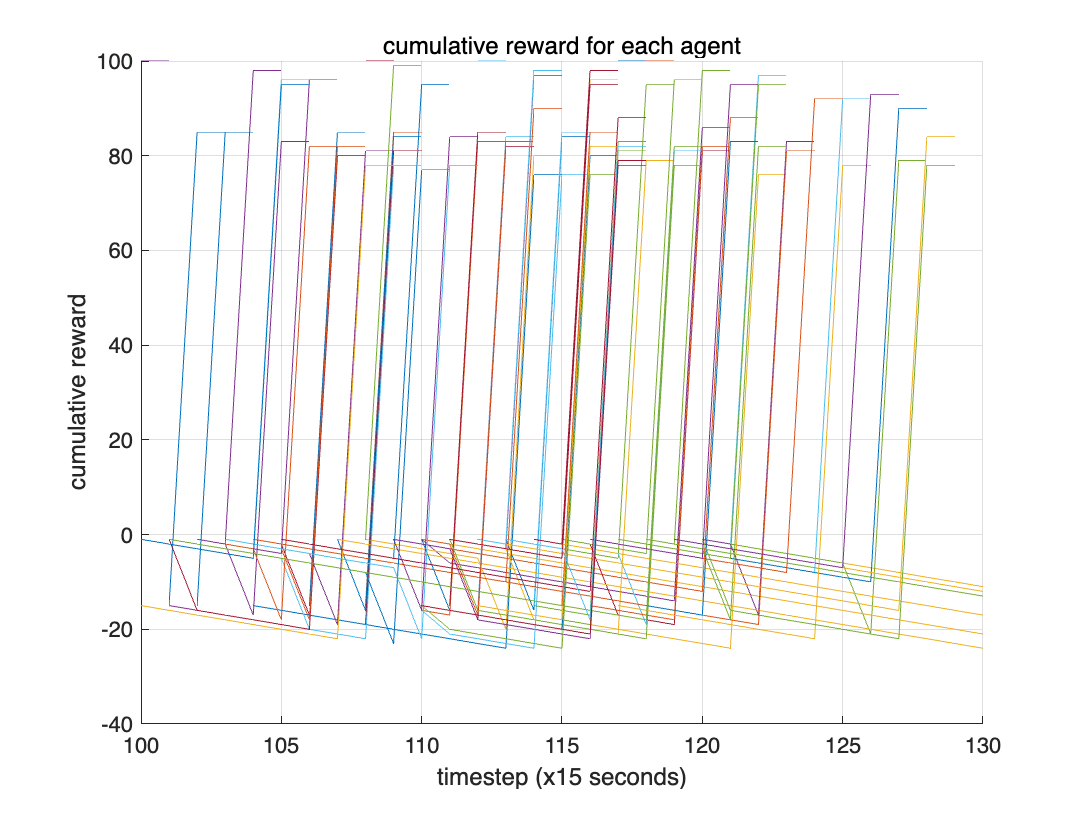

number_of_agents = length(agents_input(:,1));

final_cumulative_reward_vector = zeros(number_of_agents,1);

figure;
hold on
for agent_index = 1:number_of_agents
    cumulative_reward_each_agent = [time_index_vector', cumulative_reward_matrix(:,agent_index)];
    cumulative_reward_each_agent = cumulative_reward_each_agent(cumulative_reward_each_agent(:,2) ~= 0, :);
    plot(cumulative_reward_each_agent(:,1),cumulative_reward_each_agent(:,2))
end
hold off
grid on
title('cumulative reward for each agent')
xlabel('timestep (x15 seconds)')
ylabel('cumulative reward')

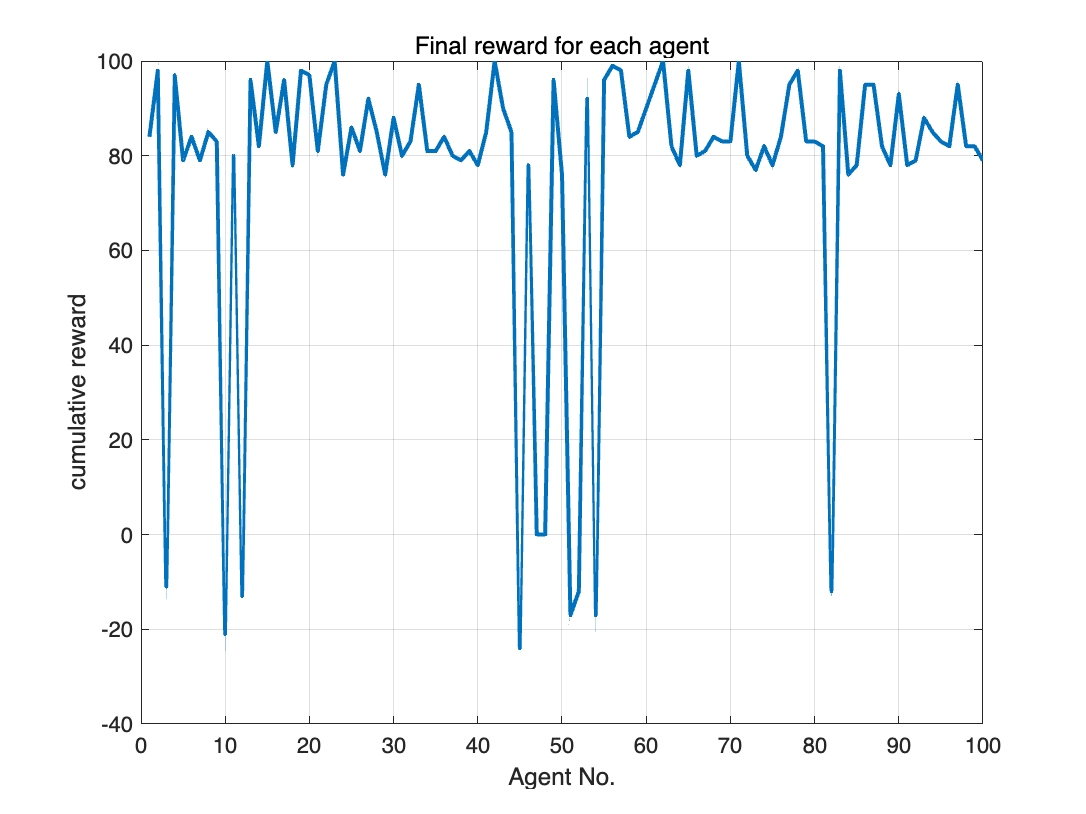


for agent_index = 1:number_of_agents
    each_agent_reward_vector = cumulative_reward_matrix(:,agent_index);
    each_agent_reward= each_agent_reward_vector(each_agent_reward_vector ~= 0);
    if isempty(each_agent_reward) == true
        continue;
    end
    final_cumulative_reward_vector(agent_index) = each_agent_reward(end);
end

figure;
plot((1:number_of_agents)',final_cumulative_reward_vector,"LineWidth",2)
grid on
title('Final reward for each agent')
xlabel('Agent No.')
ylabel('cumulative reward')

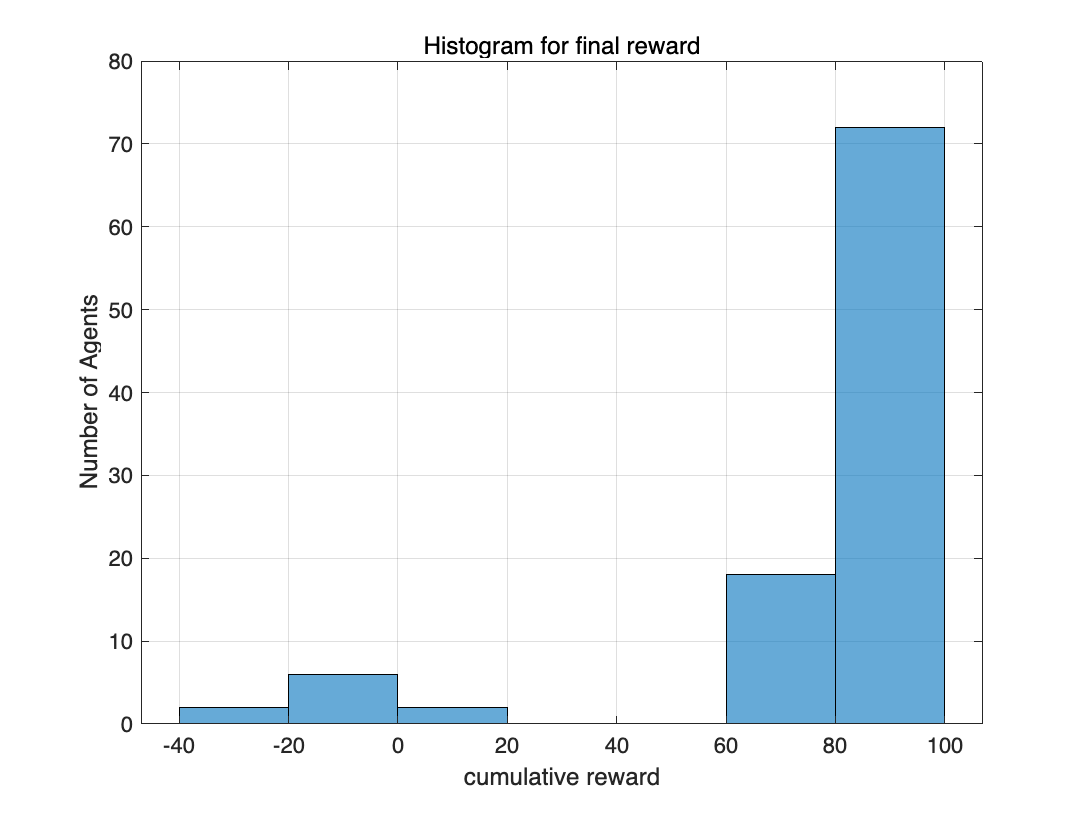


figure;
histogram(final_cumulative_reward_vector)
grid on
title('Histogram for final reward')
xlabel('cumulative reward')
ylabel('Number of Agents')

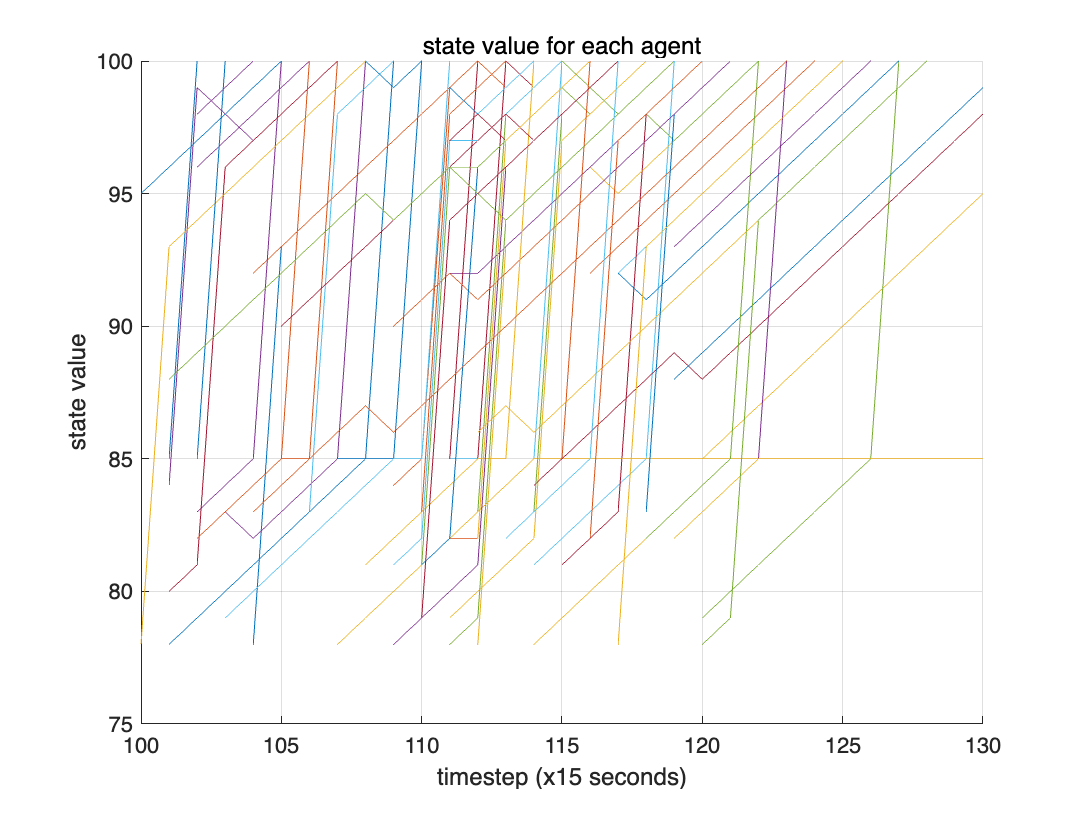



figure;
hold on
for agent_index = 1:number_of_agents

    state_value_each_agent = [time_index_vector', state_value_matrix(:,agent_index)];
    state_value_each_agent = state_value_each_agent(state_value_each_agent(:,2) ~= 0, :);

    plot(state_value_each_agent(:,1),state_value_each_agent(:,2))
end
hold off
grid on
title('state value for each agent')
xlabel('timestep (x15 seconds)')
ylabel('state value')

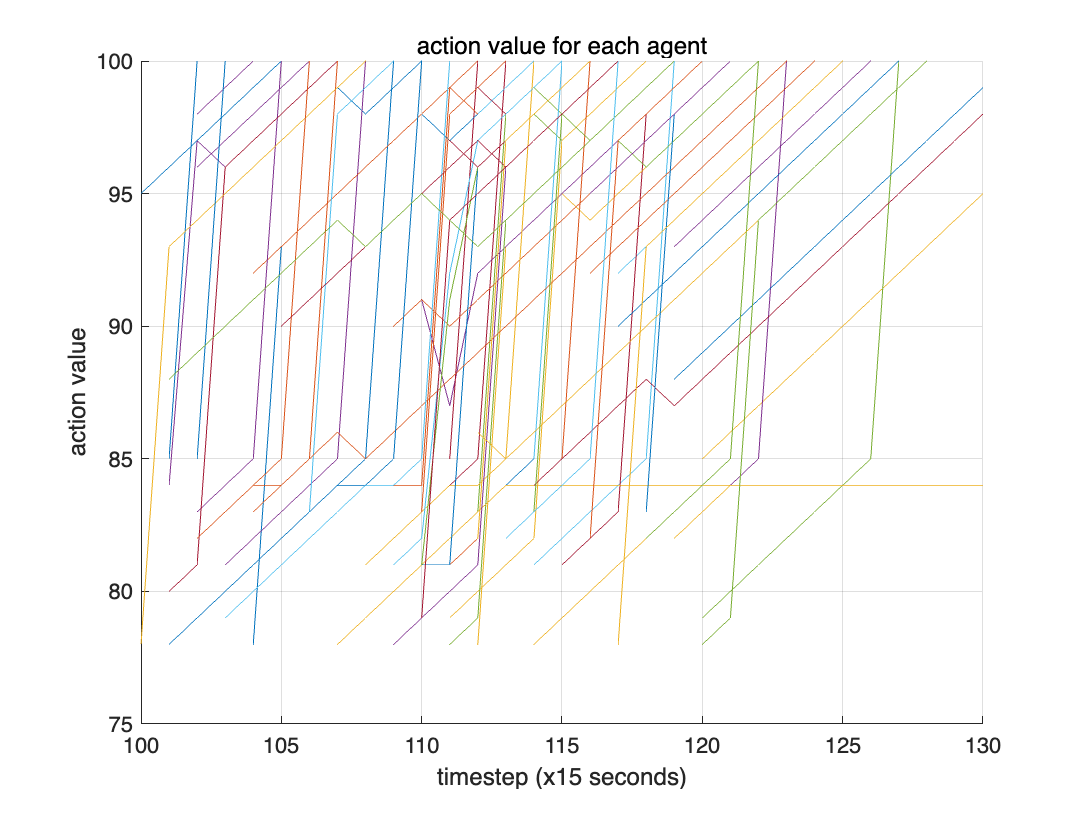


figure;
hold on
for agent_index = 1:number_of_agents

    action_value_each_agent = [time_index_vector', action_value_matrix(:,agent_index)];
    action_value_each_agent = action_value_each_agent(action_value_each_agent(:,2) ~= 0, :);
    plot(action_value_each_agent(:,1),action_value_each_agent(:,2))
end
hold off
grid on
title('action value for each agent')
xlabel('timestep (x15 seconds)')
ylabel('action value')

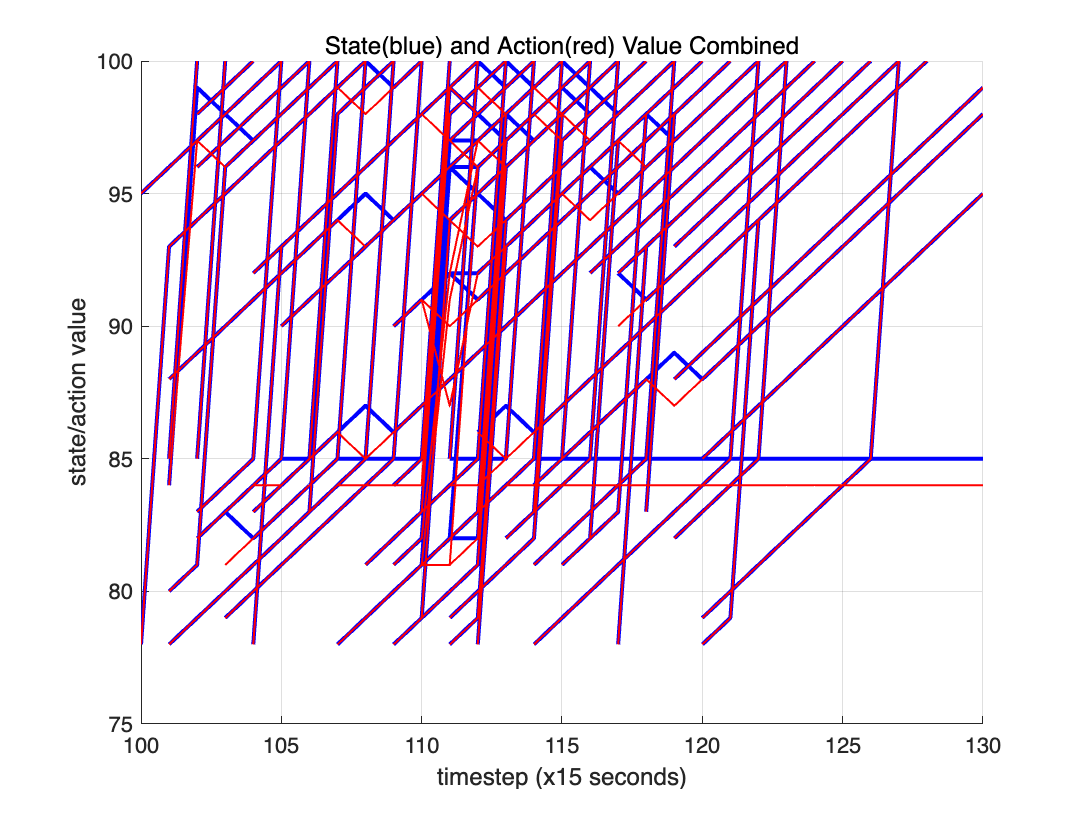




figure;
hold on
for agent_index = 1:number_of_agents

    state_value_each_agent = [time_index_vector', state_value_matrix(:,agent_index)];
    state_value_each_agent = state_value_each_agent(state_value_each_agent(:,2) ~= 0, :);

    plot(state_value_each_agent(:,1),state_value_each_agent(:,2),'b','LineWidth',2)
end


for agent_index = 1:number_of_agents

    action_value_each_agent = [time_index_vector', action_value_matrix(:,agent_index)];
    action_value_each_agent = action_value_each_agent(action_value_each_agent(:,2) ~= 0, :);
    plot(action_value_each_agent(:,1),action_value_each_agent(:,2),'r','LineWidth',1)
end
hold off
grid on
title('State(blue) and Action(red) Value Combined')
xlabel('timestep (x15 seconds)')
ylabel('state/action value')

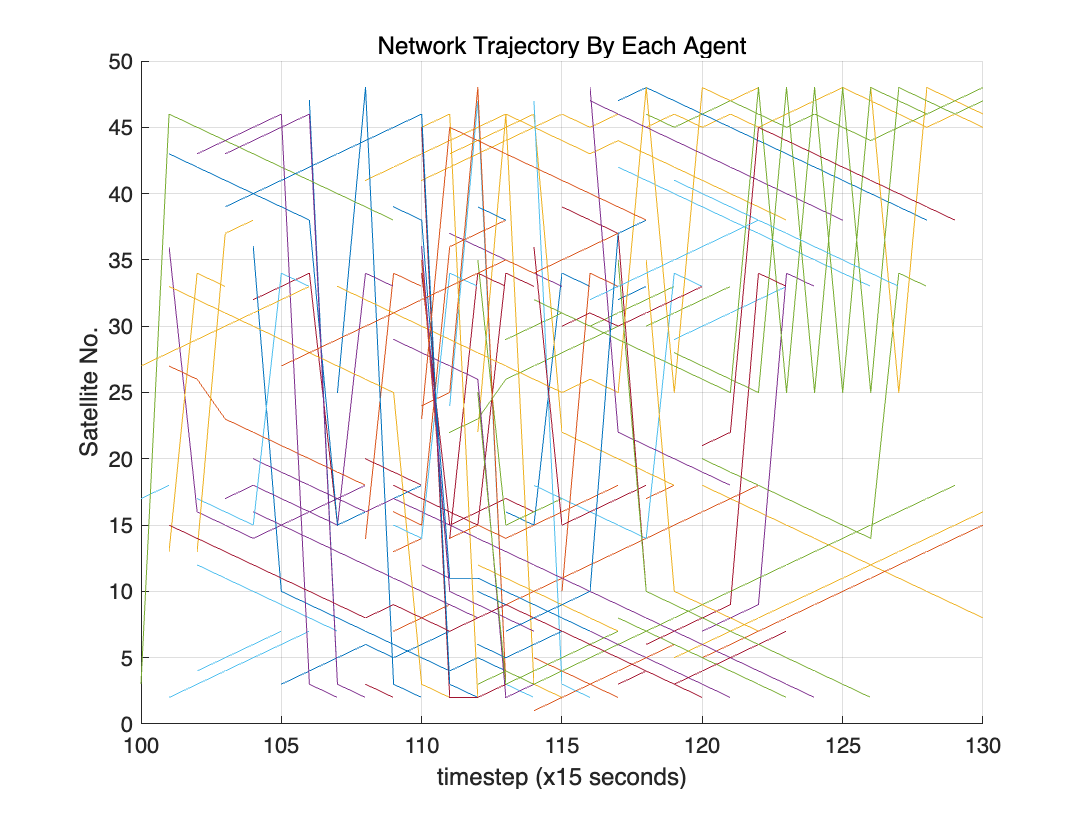



figure;
hold on
for agent_index = 1:number_of_agents
    result_sorted = [result(:,1), result(:,1+agent_index)];
    result_sorted_nonzero = result_sorted(result_sorted(:,2) ~= 0,:);
    plot(result_sorted_nonzero(:,1),result_sorted_nonzero(:,2))
end
hold off
grid on
title('Network Trajectory By Each Agent')
xlabel('timestep (x15 seconds)')
ylabel('Satellite No.')